# Problema 1 - Suplimentar

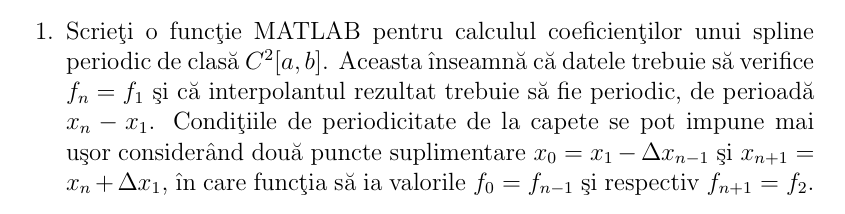

% PB1
function coef = spline_periodic(x, y)
% INPUT:
%   x - vectorul nodurilor (strict crescator): [x0, x1, ..., xn]
%   y - valorile functiei f(x) in noduri:      [y0, y1, ..., yn]
%
% OUTPUT:
%   coef - matrice (n-1) x 4 cu coeficientii spline-ului pe fiecare interval [xi, xi+1]:
%          fiecare linie: [a_i, b_i, c_i, d_i] corespunzand:
%          S_i(x) = a + b*(x - x_i) + c*(x - x_i)^2 + d*(x - x_i)^3

    n = length(x);           % numarul de noduri
    h = diff(x);             % lungimea fiecarui interval [x(i+1) - x(i)]

    % Initializam matricea A (tridiagonala cu elemente ciclice) si vectorul termenilor liberi
    A = zeros(n);           
    rhs = zeros(n, 1);      

    % ----------- CONSTRUCTIA SISTEMULUI LINEAR ------------

    % 1. Prima ecuatie (conditia de periodicitate in capatul stang)
    A(1,1)   = 2*(h(1)+h(end));   % diagonala principala
    A(1,2)   = h(1);              % urmatorul element
    A(1,end) = h(end);            % legatura ciclica cu ultimul nod
    rhs(1)   = 3*((y(2)-y(1))/h(1) - (y(end)-y(end-1))/h(end));  % derivata egala la capete

    % 2. Ecuatiile obisnuite pentru nodurile interioare (i = 2,...,n-1)
    for i = 2:n-1
        A(i,i-1) = h(i-1);                            % subdiagonala
        A(i,i)   = 2*(h(i-1) + h(i));                 % diagonala principala
        A(i,i+1) = h(i);                              % supradiagonala
        rhs(i)   = 3*((y(i+1)-y(i))/h(i) - (y(i)-y(i-1))/h(i-1));  % termenul liber
    end

    % 3. Ultima ecuatie: impune c(1) = c(n) => periodicitate a derivatelor a doua
    A(end,1)   = 1;
    A(end,end) = -1;
    rhs(end)   = 0;

    % -------------- REZOLVARE SISTEM --------------

    % Rezolva sistemul liniar A * c = rhs
    c = A \ rhs;

    % -------------- CALCUL COEFICIENTI SPLINE --------------

    a = y(1:end-1);       % coeficientul constant (fiecare S_i incepe din y(i))
    b = zeros(n-1,1);     % coeficientul lui (x - x_i)
    d = zeros(n-1,1);     % coeficientul lui (x - x_i)^3

    % Parcurgem fiecare interval [x(i), x(i+1)] pentru a calcula coeficientii
    for i = 1:n-1
        % coef. b = panta ajustata cu derivata a doua
        b(i) = (y(i+1)-y(i))/h(i) - h(i)*(2*c(i)+c(i+1))/3;

        % coef. d = diferenta derivatelor a doua, scalata
        d(i) = (c(i+1)-c(i))/(3*h(i));
    end

    % Rezultatul: coef = [a_i, b_i, c_i, d_i] pentru fiecare polinom
    coef = [a(:), b, c(1:end-1), d(:)];
end

function val = eval_spline_C(x, coef, xx)
% Evaluare spline cubic definit pe intervalele [x_i, x_{i+1}]
% INPUT:
%   x     - noduri
%   coef  - coeficientii spline-ului (n-1)x4
%   xx    - puncte unde se evalueaza spline-ul
% OUTPUT:
%   val   - vector de valori ale spline-ului in punctele xx

    val = zeros(size(xx));
    for j = 1:length(xx)
        % Gaseste intervalul unde se afla xx(j)
        i = find(x <= xx(j), 1, 'last');
        if i >= length(x)
            i = length(x)-1;
        end
        dx = xx(j) - x(i);
        a = coef(i,1); b = coef(i,2);
        c = coef(i,3); d = coef(i,4);
        val(j) = a + b*dx + c*dx^2 + d*dx^3;
    end
end

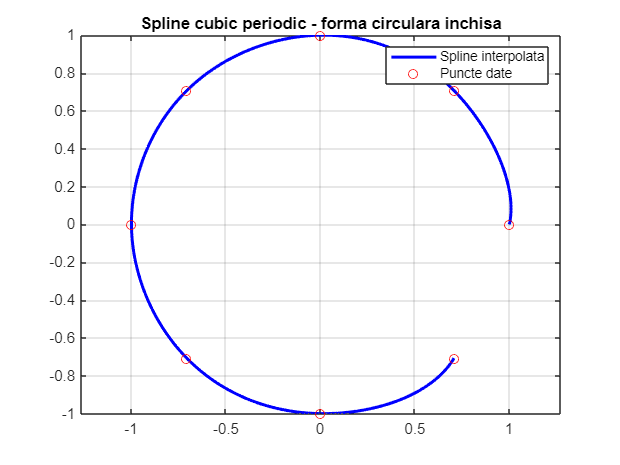

% Parametru artificial
s = 1:length(px);

% Calculeaza coeficienți spline periodic pentru fiecare axa
coef_x = spline_periodic(s, px);
coef_y = spline_periodic(s, py);

% Evaluare spline pe un set dens de puncte
ss = linspace(s(1), s(end), 300);
xx = eval_spline_C(s, coef_x, ss);
yy = eval_spline_C(s, coef_y, ss);

% Plot
figure;
plot(xx, yy, 'b-', 'LineWidth', 2); hold on;
plot(px, py, 'ro', 'MarkerSize', 6);
axis equal;
title('Spline cubic periodic - forma circulara inchisa');
legend('Spline interpolata', 'Puncte date');
grid on;